**Nastro di Moebius**

Imposto le variabili della superficie

u= linspace(0,2*pi, 500)

u =          0    0.0126    0.0252    0.0378    0.0504    0.0630    0.0755    0.0881    0.1007    0.1133    0.1259    0.1385    0.1511    0.1637    0.1763    0.1889    0.2015    0.2141    0.2266    0.2392    0.2518    0.2644    0.2770    0.2896    0.3022    0.3148    0.3274    0.3400    0.3526    0.3652    0.3777    0.3903    0.4029    0.4155    0.4281    0.4407    0.4533    0.4659    0.4785    0.4911    0.5037    0.5163    0.5288    0.5414    0.5540    0.5666    0.5792    0.5918    0.6044    0.6170


v= linspace(-1,1, 500)

v =    -1.0000   -0.9960   -0.9920   -0.9880   -0.9840   -0.9800   -0.9760   -0.9719   -0.9679   -0.9639   -0.9599   -0.9559   -0.9519   -0.9479   -0.9439   -0.9399   -0.9359   -0.9319   -0.9279   -0.9238   -0.9198   -0.9158   -0.9118   -0.9078   -0.9038   -0.8998   -0.8958   -0.8918   -0.8878   -0.8838   -0.8798   -0.8758   -0.8717   -0.8677   -0.8637   -0.8597   -0.8557   -0.8517   -0.8477   -0.8437   -0.8397   -0.8357   -0.8317   -0.8277   -0.8236   -0.8196   -0.8156   -0.8116   -0.8076   -0.8036


Definisco una griglia per le variabili U e V

[U, V] = meshgrid(u, v);

Definisco le componenti

X=(2 - V .* sin(U / 2)) .* sin(U)

X =          0    0.0253    0.0507    0.0762    0.1020    0.1278    0.1538    0.1799    0.2062    0.2326    0.2591    0.2857    0.3124    0.3392    0.3662    0.3932    0.4203    0.4475    0.4748    0.5022    0.5296    0.5572    0.5847    0.6124    0.6400    0.6678    0.6955    0.7233    0.7512    0.7790    0.8069    0.8348    0.8627    0.8906    0.9185    0.9464    0.9743    1.0021    1.0300    1.0578    1.0855    1.1133    1.1409    1.1686    1.1961    1.2236    1.2510    1.2784    1.3057    1.3328
         0    0.0253    0.0507    0.0762    0.1020    0.1278    0.1538    0.1799    0.2062    0.2325    0.2590    0.2856    0.3124    0.3392    0.3661    0.3931    0.4203    0.4475    0.4747    0.5021    0.5295    0.5570    0.5846    0.6122    0.6399    0.6676    0.6953    0.7231    0.7509    0.7788    0.8066    0.8345    0.8624    0.8903    0.9181    0.9460    0.9739    1.0017    1.0295    1.0573    1.0851    1.1128    1.1404    1.1680    1.1955    1.2230    1.2504    1.2777    1.3050    1

Y=(2 - V .* sin(U / 2)) .* cos(U)

Y =     2.0000    2.0061    2.0120    2.0174    2.0226    2.0274    2.0320    2.0361    2.0400    2.0434    2.0466    2.0494    2.0518    2.0539    2.0557    2.0571    2.0581    2.0587    2.0590    2.0590    2.0585    2.0577    2.0566    2.0550    2.0531    2.0508    2.0481    2.0450    2.0416    2.0377    2.0335    2.0289    2.0239    2.0185    2.0128    2.0066    2.0000    1.9931    1.9857    1.9780    1.9699    1.9614    1.9524    1.9431    1.9334    1.9233    1.9128    1.9019    1.8906    1.8789
    2.0000    2.0061    2.0119    2.0174    2.0225    2.0273    2.0318    2.0359    2.0398    2.0432    2.0463    2.0491    2.0515    2.0536    2.0553    2.0567    2.0577    2.0583    2.0586    2.0585    2.0581    2.0572    2.0560    2.0544    2.0525    2.0502    2.0475    2.0444    2.0409    2.0371    2.0328    2.0282    2.0232    2.0178    2.0120    2.0058    1.9992    1.9923    1.9849    1.9771    1.9690    1.9605    1.9515    1.9422    1.9325    1.9223    1.9118    1.9009    1.8896    1

Z=V .* cos(U / 2)

Z =    -1.0000   -1.0000   -0.9999   -0.9998   -0.9997   -0.9995   -0.9993   -0.9990   -0.9987   -0.9984   -0.9980   -0.9976   -0.9971   -0.9967   -0.9961   -0.9955   -0.9949   -0.9943   -0.9936   -0.9929   -0.9921   -0.9913   -0.9904   -0.9895   -0.9886   -0.9876   -0.9866   -0.9856   -0.9845   -0.9834   -0.9822   -0.9810   -0.9798   -0.9785   -0.9772   -0.9758   -0.9744   -0.9730   -0.9715   -0.9700   -0.9685   -0.9669   -0.9652   -0.9636   -0.9619   -0.9601   -0.9584   -0.9565   -0.9547   -0.9528
   -0.9960   -0.9960   -0.9959   -0.9958   -0.9957   -0.9955   -0.9953   -0.9950   -0.9947   -0.9944   -0.9940   -0.9936   -0.9932   -0.9927   -0.9921   -0.9916   -0.9909   -0.9903   -0.9896   -0.9889   -0.9881   -0.9873   -0.9865   -0.9856   -0.9846   -0.9837   -0.9827   -0.9816   -0.9806   -0.9794   -0.9783   -0.9771   -0.9758   -0.9746   -0.9733   -0.9719   -0.9705   -0.9691   -0.9676   -0.9661   -0.9646   -0.9630   -0.9614   -0.9597   -0.9580   -0.9563   -0.9545   -0.9527   -0.9509   -0

Apro ambiente figure e plotto la superficie

figure
surf(X, Y, Z, "EdgeColor","none")
colormap("summer")
shading interp

Gestisco dettagli

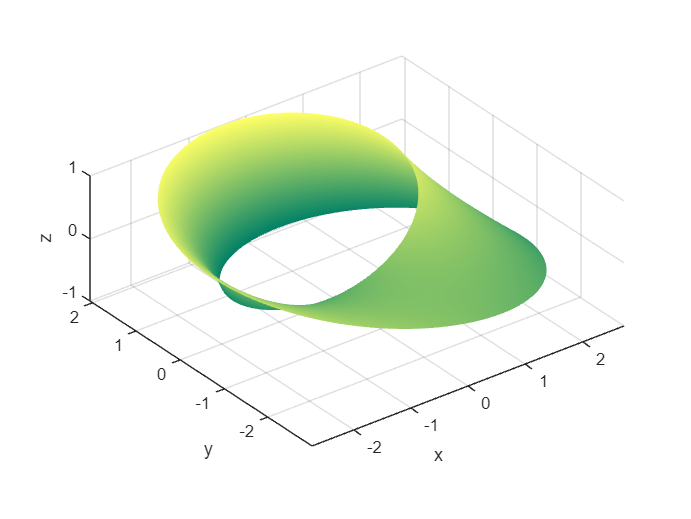

axis equal
xlabel("x")
ylabel("y")
zlabel("z", Rotation=90)
view(3)